% --- MAIN SCRIPT FOR NONLINEAR BEAM-COLUMN ANALYSIS (RITZ METHOD) ---
% Includes both transverse (P) and axial (P_axial) loads.
% Solved with an EXPLICIT Newton-Raphson solver.

clear; clc; close all;

%% 1. Define Symbolic Variables and Functions
syms x L E A I P P_axial real; % <-- ADDED P_axial
syms c2 c3 d1 d2 d3 d4 d5 real;

% Polynomials are unchanged
w_sym = c2*x^2 + c3*x^3;
u_sym = d1*x + d2*x^2 + d3*x^3 + d4*x^4 + d5*x^5;

% Strains are unchanged
dw_dx_sym = diff(w_sym, x);
d2w_dx2_sym = diff(w_sym, x, 2);
du_dx_sym = diff(u_sym, x);
eps0_sym = du_dx_sym + 0.5 * dw_dx_sym^2;
eps1_sym = -d2w_dx2_sym;

% Strain Energy is unchanged
U_density = 0.5 * (E*A * eps0_sym^2 + E*I * eps1_sym^2);
U_total = int(U_density, x, 0, L);

% --- External Work now includes the axial force ---
W_ext = P * subs(w_sym, x, L) + P_axial * subs(u_sym, x, L); % <-- MODIFIED

% Total Potential Energy
Pi_total = U_total - W_ext;

%% 2. Generate the Residual Vector and Tangent Stiffness Matrix
coeffs = [c2, c3, d1, d2, d3, d4, d5];

fprintf('Generating the Residual and Tangent Stiffness expressions...\n');

Generating the Residual and Tangent Stiffness expressions...


R_expr = jacobian(Pi_total, coeffs)'; % Residual is d(Pi)/d(coeff)
K_T_expr = jacobian(R_expr, coeffs);  % Tangent Stiffness is d(R)/d(coeff)

% Convert to fast MATLAB function handles
fprintf('Converting expressions to MATLAB function handles...\n');

Converting expressions to MATLAB function handles...


vars = [{L, E, A, I, P, P_axial}, coeffs]; % <-- ADDED P_axial to vars
R_handle = matlabFunction(R_expr, 'Vars', vars);
K_T_handle = matlabFunction(K_T_expr, 'Vars', vars);

%% 3. Numerical Analysis Setup
% Define numerical values
L_val = 1.0; E_val = 210e9; b_val = 0.05; h_val = 0.05;
A_val = b_val * h_val; I_val = b_val * h_val^3 / 12;

% Analysis Control
P_max = -200; % Transverse Load
P_axial_val = -5e7; % <-- SET AXIAL LOAD HERE (Negative for compression)

num_steps = 20;
load_steps = linspace(P_max/num_steps, P_max, num_steps);
axial_load_steps = linspace(P_axial_val/num_steps, P_axial_val, num_steps); % Apply axial load proportionally

max_iter = 10;
tolerance = 1e-6;

%% 4. Solve with Incremental-Iterative Newton-Raphson
C = zeros(length(coeffs), 1);
C_history = zeros(length(coeffs), num_steps);

for step = 1:num_steps
    current_load_P = load_steps(step);
    current_load_P_axial = axial_load_steps(step); % <-- Get current axial load
    
    fprintf('\nLoad Step %d/%d, P = %.2e N, P_axial = %.2e N\n', ...
        step, num_steps, current_load_P, current_load_P_axial);
    
    for iter = 1:max_iter
        c_vals = num2cell(C');
        
        % Calculate Residual and Tangent Stiffness using the function handles
        R = R_handle(L_val, E_val, A_val, I_val, current_load_P, current_load_P_axial, c_vals{:});
        K_T = K_T_handle(L_val, E_val, A_val, I_val, current_load_P, current_load_P_axial, c_vals{:});
        
        norm_R = norm(R);
        fprintf('  Iteration %d: Residual Norm = %.4e\n', iter, norm_R);
        
        if norm_R < tolerance
            fprintf('  Convergence achieved in %d iterations.\n', iter);
            break;
        end
        if iter == max_iter, warning('Max iterations reached.'); break; end

        % Solve for the increment and update coefficients
        delta_C = -K_T \ R;
        C = C + delta_C;
    end
    
    C_history(:, step) = C;
end


Load Step 1/20, P = -1.00e+01 N, P_axial = -2.50e+06 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 1.4018e+02
  Iteration 3: Residual Norm = 1.3169e+00
  Iteration 4: Residual Norm = 5.2491e-10


  Convergence achieved in 4 iterations.



Load Step 2/20, P = -2.00e+01 N, P_axial = -5.00e+06 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 9.5219e+00
  Iteration 3: Residual Norm = 1.8759e-01
  Iteration 4: Residual Norm = 6.3911e-10


  Convergence achieved in 4 iterations.



Load Step 3/20, P = -3.00e+01 N, P_axial = -7.50e+06 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 4.9798e+00
  Iteration 3: Residual Norm = 5.8646e-03
  Iteration 4: Residual Norm = 1.2570e-09


  Convergence achieved in 4 iterations.



Load Step 4/20, P = -4.00e+01 N, P_axial = -1.00e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 5.7323e-01
  Iteration 3: Residual Norm = 4.0518e-05
  Iteration 4: Residual Norm = 3.4702e-09


  Convergence achieved in 4 iterations.



Load Step 5/20, P = -5.00e+01 N, P_axial = -1.25e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 1.8856e-01
  Iteration 3: Residual Norm = 2.8987e-06
  Iteration 4: Residual Norm = 2.0341e-09


  Convergence achieved in 4 iterations.



Load Step 6/20, P = -6.00e+01 N, P_axial = -1.50e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 8.9166e-02
  Iteration 3: Residual Norm = 4.6615e-07


  Convergence achieved in 3 iterations.



Load Step 7/20, P = -7.00e+01 N, P_axial = -1.75e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 5.0939e-02
  Iteration 3: Residual Norm = 1.2191e-07


  Convergence achieved in 3 iterations.



Load Step 8/20, P = -8.00e+01 N, P_axial = -2.00e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 3.2675e-02
  Iteration 3: Residual Norm = 3.3194e-08


  Convergence achieved in 3 iterations.



Load Step 9/20, P = -9.00e+01 N, P_axial = -2.25e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 2.2654e-02
  Iteration 3: Residual Norm = 1.5091e-08


  Convergence achieved in 3 iterations.



Load Step 10/20, P = -1.00e+02 N, P_axial = -2.50e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 1.6601e-02
  Iteration 3: Residual Norm = 1.2048e-08


  Convergence achieved in 3 iterations.



Load Step 11/20, P = -1.10e+02 N, P_axial = -2.75e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 1.2679e-02
  Iteration 3: Residual Norm = 4.7673e-09


  Convergence achieved in 3 iterations.



Load Step 12/20, P = -1.20e+02 N, P_axial = -3.00e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 9.9979e-03
  Iteration 3: Residual Norm = 5.1628e-09


  Convergence achieved in 3 iterations.



Load Step 13/20, P = -1.30e+02 N, P_axial = -3.25e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 8.0853e-03
  Iteration 3: Residual Norm = 4.6015e-09


  Convergence achieved in 3 iterations.



Load Step 14/20, P = -1.40e+02 N, P_axial = -3.50e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 6.6741e-03
  Iteration 3: Residual Norm = 1.0613e-08


  Convergence achieved in 3 iterations.



Load Step 15/20, P = -1.50e+02 N, P_axial = -3.75e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 5.6032e-03
  Iteration 3: Residual Norm = 2.0274e-08


  Convergence achieved in 3 iterations.



Load Step 16/20, P = -1.60e+02 N, P_axial = -4.00e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 4.7715e-03
  Iteration 3: Residual Norm = 1.0949e-08


  Convergence achieved in 3 iterations.



Load Step 17/20, P = -1.70e+02 N, P_axial = -4.25e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 4.1127e-03
  Iteration 3: Residual Norm = 1.2737e-08


  Convergence achieved in 3 iterations.



Load Step 18/20, P = -1.80e+02 N, P_axial = -4.50e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 3.5819e-03
  Iteration 3: Residual Norm = 1.3310e-08


  Convergence achieved in 3 iterations.



Load Step 19/20, P = -1.90e+02 N, P_axial = -4.75e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 3.1479e-03
  Iteration 3: Residual Norm = 6.8073e-09


  Convergence achieved in 3 iterations.



Load Step 20/20, P = -2.00e+02 N, P_axial = -5.00e+07 N


  Iteration 1: Residual Norm = 5.5902e+06
  Iteration 2: Residual Norm = 2.7886e-03
  Iteration 3: Residual Norm = 1.1944e-08


  Convergence achieved in 3 iterations.



%% 5. Post-Processing and Plotting
fprintf('\n--- Analysis Complete ---\n');


--- Analysis Complete ---


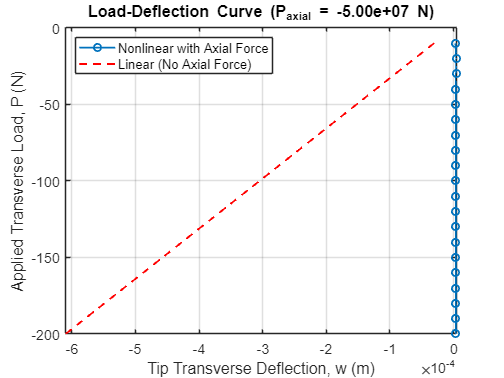

tip_deflections = zeros(1, num_steps);
for i = 1:num_steps
    c2_val = C_history(1, i);
    c3_val = C_history(2, i);
    tip_deflections(i) = c2_val * L_val^2 + c3_val * L_val^3;
end

figure('Name', 'Load-Deflection with Axial Force');
plot(tip_deflections, load_steps, '-o', 'LineWidth', 1.5, 'DisplayName', 'Nonlinear with Axial Force');
hold on;
w_linear = (load_steps * L_val^3) / (3 * E_val * I_val);
plot(w_linear, load_steps, '--r', 'LineWidth', 1.5, 'DisplayName', 'Linear (No Axial Force)');

grid on;
title(sprintf('Load-Deflection Curve (P_{axial} = %.2e N)', P_axial_val));
xlabel('Tip Transverse Deflection, w (m)');
ylabel('Applied Transverse Load, P (N)');
legend('show', 'Location', 'NorthWest');
set(gca, 'FontSize', 12);



% --- Section 6: Post-Processing and Plotting Final Deformed Shape ---

fprintf('\n--- Plotting Final Deformed Shape ---\n');


--- Plotting Final Deformed Shape ---


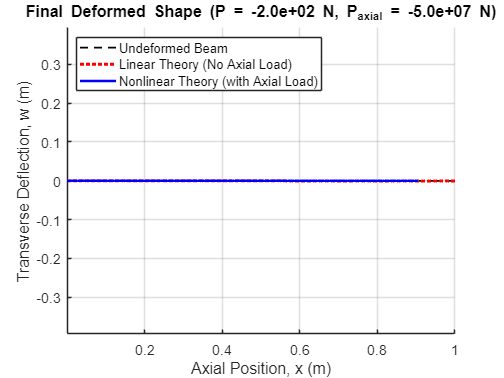


% 1. Create a set of points along the beam's length
x_points = linspace(0, L_val, 200);

% 2. Calculate the NONLINEAR deflected shape using the solved coefficients
% Substitute the final solved coefficients (C) into the symbolic functions
w_sol_final(x) = subs(w_sym, coeffs, C');
u_sol_final(x) = subs(u_sym, coeffs, C');

% Evaluate the nonlinear displacements at each point
w_nonlinear = double(w_sol_final(x_points));
u_nonlinear = double(u_sol_final(x_points));

% The final position in the nonlinear case is (x + u, w)
x_deformed_nonlinear = x_points + u_nonlinear;

% 3. Calculate the standard LINEAR deflected shape (ignoring axial force effect)
P_final = current_load_P;
w_linear = (P_final * x_points.^2) ./ (6 * E_val * I_val) .* (3 * L_val - x_points);

% 4. Create the plot
figure('Name', 'Final Deformed Shape of the Beam-Column');
hold on;

% Plot the original, undeformed beam
plot([0, L_val], [0, 0], 'k--', 'LineWidth', 1.5, 'DisplayName', 'Undeformed Beam');

% Plot the linear deflected shape
plot(x_points, w_linear, 'r:', 'LineWidth', 2.5, 'DisplayName', 'Linear Theory (No Axial Load)');

% Plot the nonlinear deflected shape
plot(x_deformed_nonlinear, w_nonlinear, 'b-', 'LineWidth', 2, 'DisplayName', 'Nonlinear Theory (with Axial Load)');

% Add labels, title, and legend
title(sprintf('Final Deformed Shape (P = %.1e N, P_{axial} = %.1e N)', P_final, P_axial_val));
xlabel('Axial Position, x (m)');
ylabel('Transverse Deflection, w (m)');
legend('show', 'Location', 'NorthWest');
grid on;
axis equal; % Use equal scaling to see the true, undistorted shape
set(gca, 'FontSize', 12);

hold off;